Exercício 5

Suponha que o(s) motor(es) de um avião pode(m) falhar com probabilidade p e que as falhas são independentes

entre motores. Suponha ainda que o avião se despenha se mais de metade dos motores falharem. 

Nestas condições, prefere voar num avião com 2 ou 4 motores? 

Utilize a distribuição que considerar mais adequada.

%2 motores
% prob = 2c2 * p^2 *(1-p)^0
% prob = p*p

%4 motores
% prob = 4c3 * p^3 *(1-p)^1 + 4c4 * p^4 *(1-p)^0
% prob = 4*p^3 + p^4

%quociente
% 1/(4*p + p^2)

p = logspace(-3,log10(1/2),100);

p =     0.0010    0.0011    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0023    0.0024    0.0026    0.0027    0.0029    0.0031    0.0033    0.0035    0.0037    0.0040    0.0042    0.0045    0.0048    0.0051    0.0054    0.0058    0.0062    0.0066    0.0070    0.0075    0.0079    0.0085    0.0090    0.0096    0.0102    0.0109    0.0116    0.0123    0.0131    0.0140    0.0149    0.0158    0.0169    0.0180    0.0191    0.0204    0.0217



probc2 = zeros(1,100);
probc4 = zeros(1,100);
i = 1;

for f = p
        
    probc2(i) = prob_teorica(2,2,f);
    probc4(i) = prob_teorica(3,4,f) + prob_teorica(4,4,f);
    i = i + 1;

end

f = 1.0000e-03

f = 0.0011

f = 0.0011

f = 0.0012

f = 0.0013

f = 0.0014

f = 0.0015

f = 0.0016

f = 0.0017

f = 0.0018

f = 0.0019

f = 0.0020

f = 0.0021

f = 0.0023

f = 0.0024

f = 0.0026

f = 0.0027

f = 0.0029

f = 0.0031

f = 0.0033

f = 0.0035

f = 0.0037

f = 0.0040

f = 0.0042

f = 0.0045

f = 0.0048

f = 0.0051

f = 0.0054

f = 0.0058

f = 0.0062

f = 0.0066

f = 0.0070

f = 0.0075

f = 0.0079

f = 0.0085

f = 0.0090

f = 0.0096

f = 0.0102

f = 0.0109

f = 0.0116

f = 0.0123

f = 0.0131

f = 0.0140

f = 0.0149

f = 0.0158

f = 0.0169

f = 0.0180

f = 0.0191

f = 0.0204

f = 0.0217

f = 0.0231

f = 0.0246

f = 0.0262

f = 0.0279

f = 0.0297

f = 0.0316

f = 0.0336

f = 0.0358

f = 0.0381

f = 0.0406

f = 0.0432

f = 0.0460

f = 0.0490

f = 0.0522

f = 0.0556

f = 0.0592

f = 0.0630

f = 0.0671

f = 0.0714

f = 0.0761

f = 0.0810

f = 0.0862

f = 0.0918

f = 0.0978

f = 0.1041

f = 0.1108

f = 0.1180

f = 0.1257

f = 0.1338

f = 0.1425

f = 0.1517

f = 0.1615

f = 0.1720

f = 0.1831

f = 0.1950

f = 0.2076

f = 0.2211

f = 0.2354

f = 0.2507

f = 0.2669

f = 0.2842

f = 0.3026

f = 0.3222

f = 0.3431

f = 0.3653

f = 0.3890

f = 0.4142

f = 0.4410

f = 0.4696

f = 0.5000

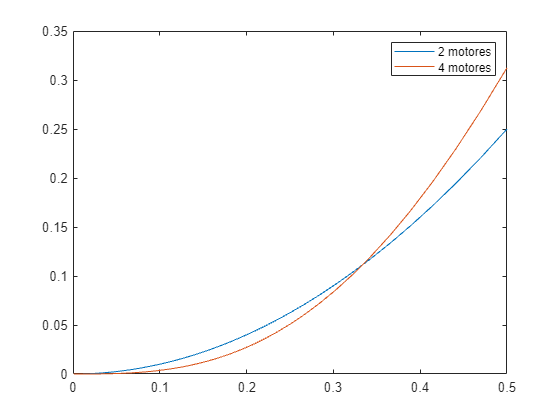


plot(p,probc2)
hold on 
plot(p, probc4)
hold off

legend('2 motores','4 motores')